# RNN Classification of Mental Workload EEG

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\keyen\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


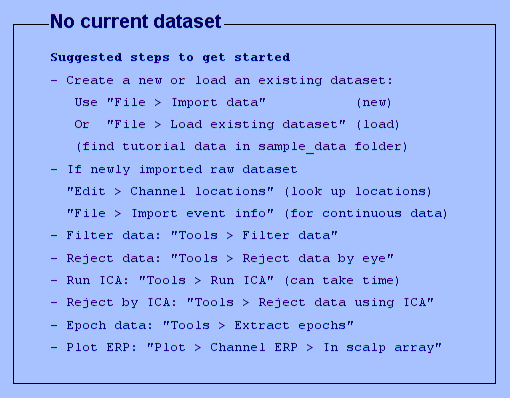

You are using the latest version of EEGLAB.
Hey I am now importing data for Subject 01
pop_loadset(): loading file P01\S1\eeg\alldata_sbj01_sess1_MATBdiff.set ...
pop_loadset(): loading file P01\S1\eeg\alldata_sbj01_sess1_MATBmed.set ...
pop_loadset(): loading file P01\S1\eeg\alldata_sbj01_sess1_MATBeasy.set ...
pop_loadset(): loading file P01\S1\eeg\alldata_sbj01_sess1_RS.set ...
pop_loadset(): loading file P01\S2\eeg\alldata_sbj01_sess2_MATBdiff.set ...
pop_loadset(): loading file P01\S2\eeg\alldata_sbj01_sess2_MATBmed.set ...
pop_loadset(): loading file P01\S2\eeg\alldata_sbj01_sess2_MATBeasy.set ...
pop_loadset(): loading file P01\S2\eeg\alldata_sbj01_sess2_RS.set ...


data_process(1)

load('subject_1.mat')

eeg = cat(3,t_testset,t_trainingset);
label = cat(1,testbin,trainingbin);

features = extract_features(eeg);

Extracting features from trial 1Extracting features from trial 2Extracting features from trial 3Extracting features from trial 4Extracting features from trial 5Extracting features from trial 6Extracting features from trial 7Extracting features from trial 8Extracting features from trial 9Extracting features from trial 10Extracting features from trial 11Extracting features from trial 12Extracting features from trial 13Extracting features from trial 14Extracting features from trial 15Extracting features from trial 16Extracting features from trial 17Extracting features from trial 18Extracting features from trial 19Extracting features from trial 20Extracting features from trial 21Extracting features from trial 22Extracting features from trial 23Extracting features from trial 24Extracting features from trial 25Extracting features from trial 26Extracting features from trial 27Extracting features from trial 28Extracting features from trial 29Extracting features from trial 30Extracting features

x = make_cellarray_eeg(features);
y = make_categorical_label(label)';

n_validationSet = 10;
[xtrain,ytrain,xval,yval]=validation_split_kfold(x,y,n_validationSet);

nsets = 10

valid = K-fold cross validation partition
   NumObservations: 894
       NumTestSets: 10
         TrainSize: 805  804  804  804  804  805  805  805  805  805
          TestSize: 89  90  90  90  90  89  89  89  89  89

parameters.minibatch = 20;
parameters.maxepochs = 100;
for a = 1:n_validationSet
    
    parameters.xval = xval{a};
    parameters.yval = yval{a};

    options{a} = training_options_bilstm(parameters);
end

ans = 20

ans = 20

ans = 20

ans = 20

ans = 20

ans = 20

ans = 20

ans = 20

ans = 20

ans = 20

layers = bilstm_network_architecture()

layers =   12×1 Layer array with layers:

     1   'Input'                           Sequence Input          Sequence input with 61 dimensions
     2   'BiLSTM_layer'                    BiLSTM                  BiLSTM with 256 hidden units
     3   'Dropout_layer'                   Dropout                 20% dropout
     4   'Batch_normalization_layer_I'     Batch Normalization     Batch normalization
     5   'LSTM_layer_I'                    LSTM                    LSTM with 128 hidden units
     6   'Batch_normalization_layer_II'    Batch Normalization     Batch normalization
     7   'LSTM_layer_II'                   LSTM                    LSTM with 64 hidden units
     8   'Batch_normalization_layer_III'   Batch Normalization     Batch normalization
     9   'Fully_connected_layer_I'         Fully Connected         16 fully connected layer
    10   'Fully_connected_layer_II'        Fully Connected       

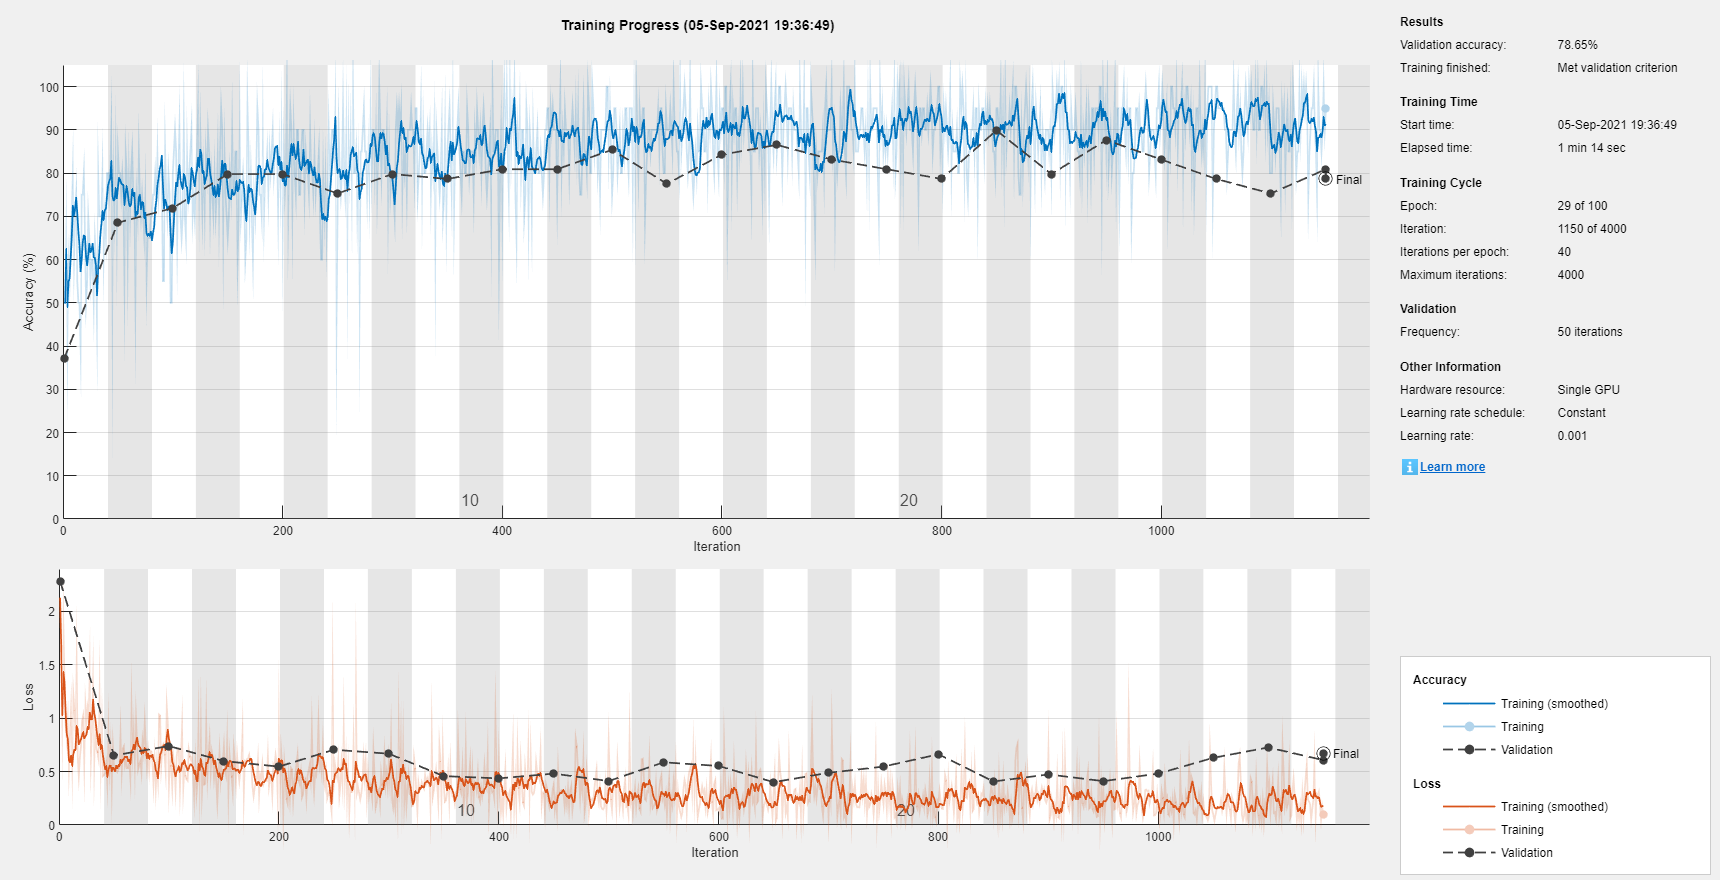

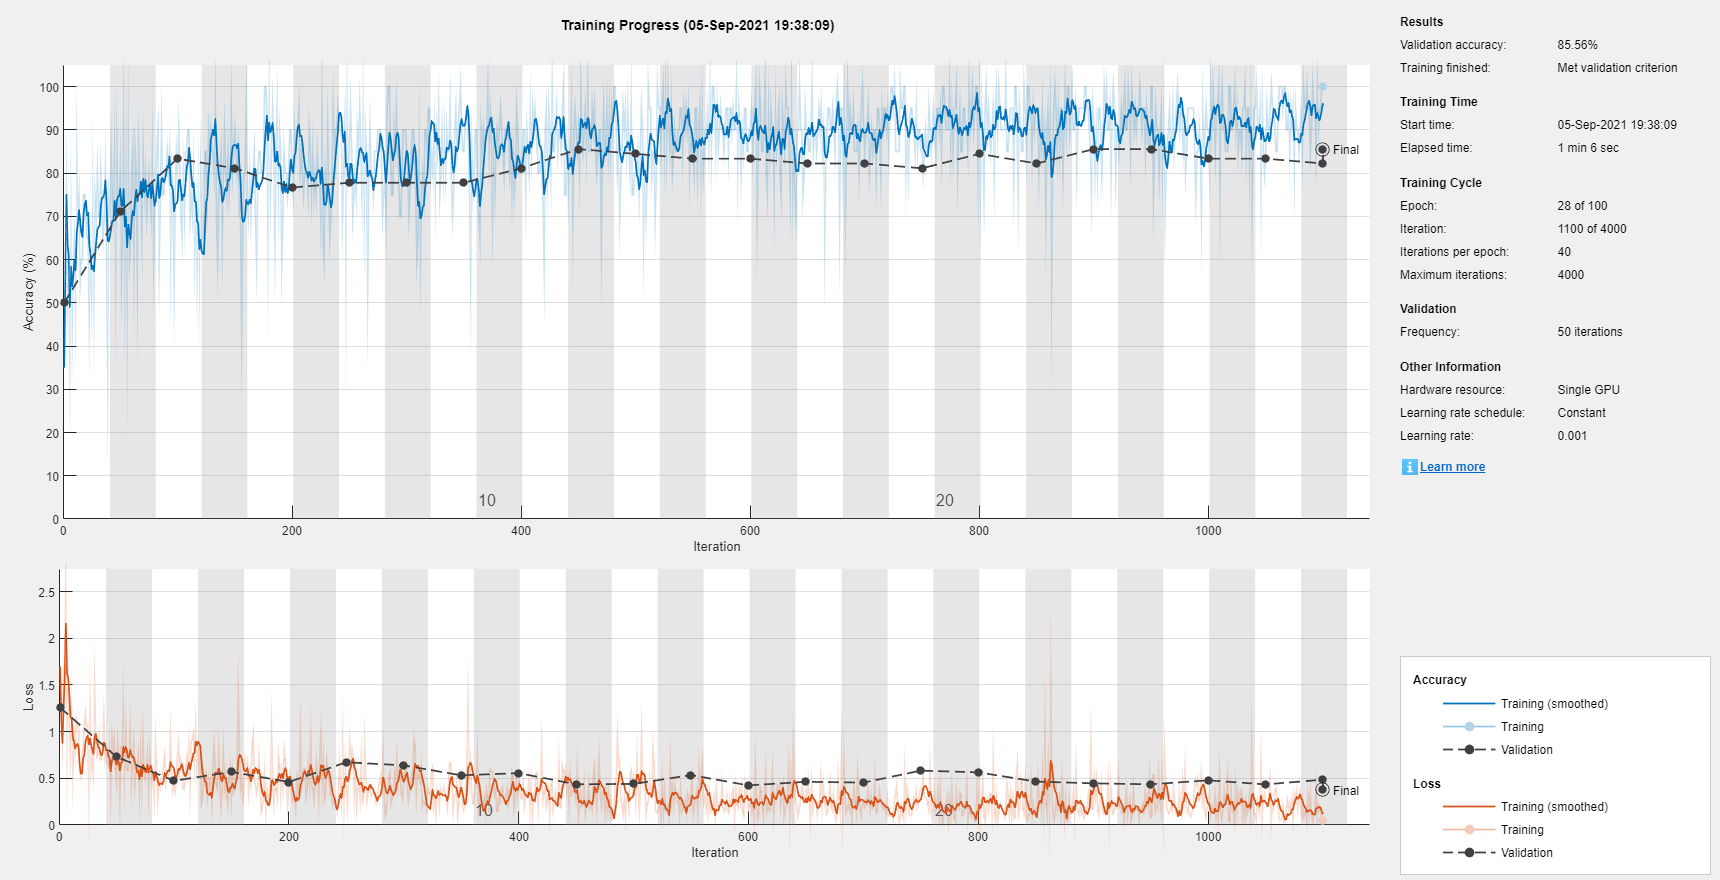

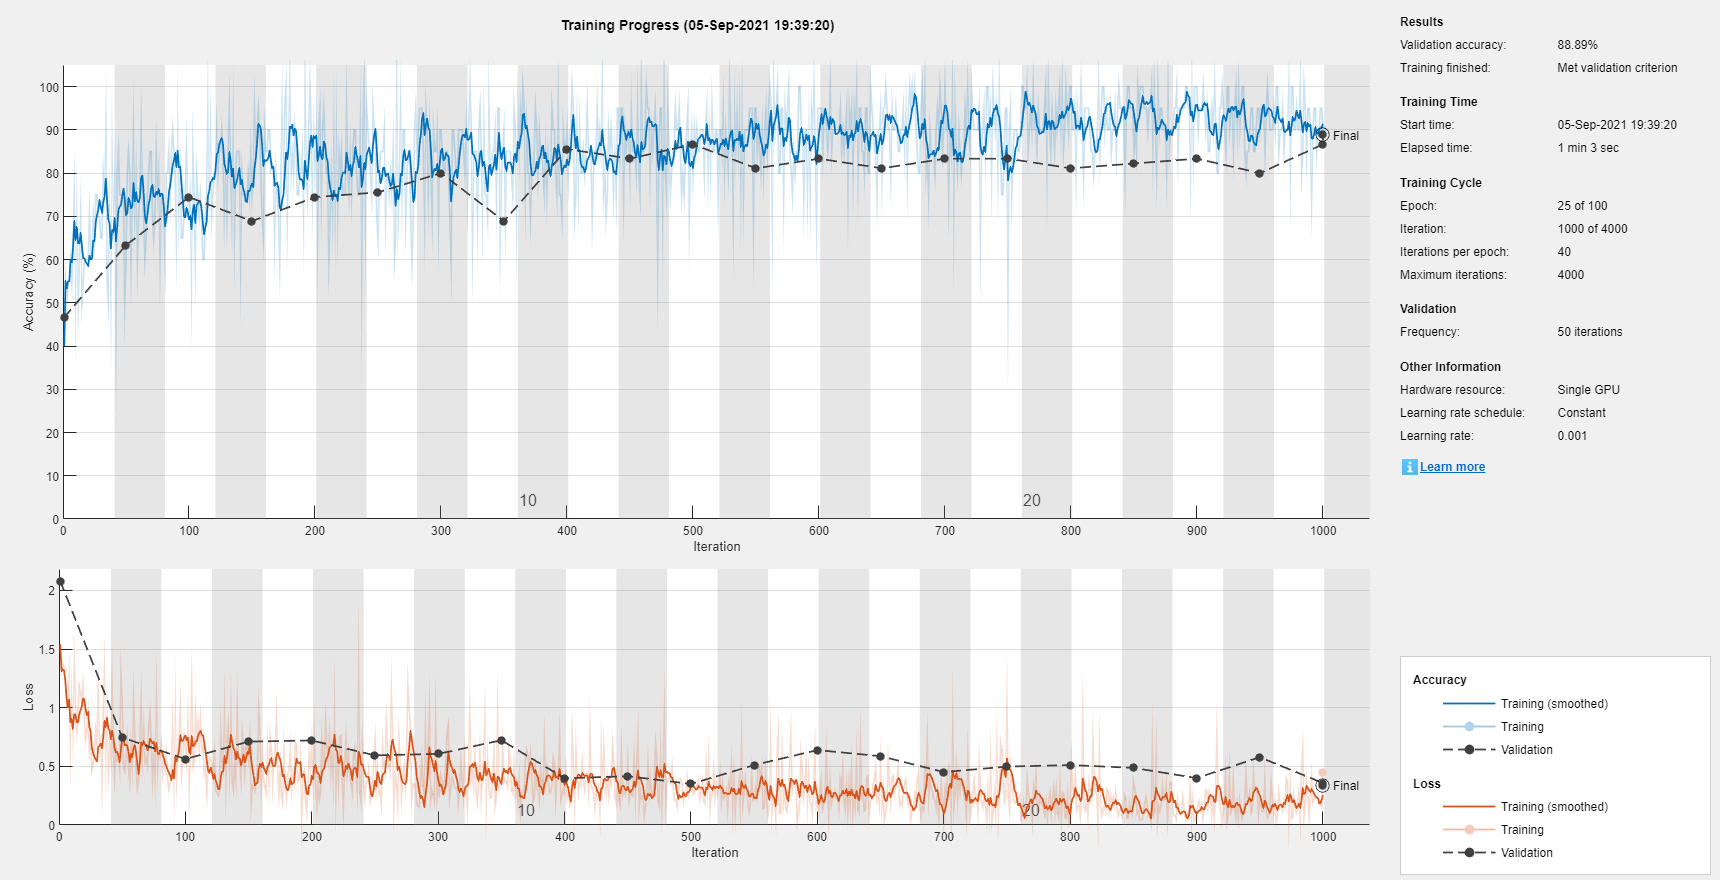

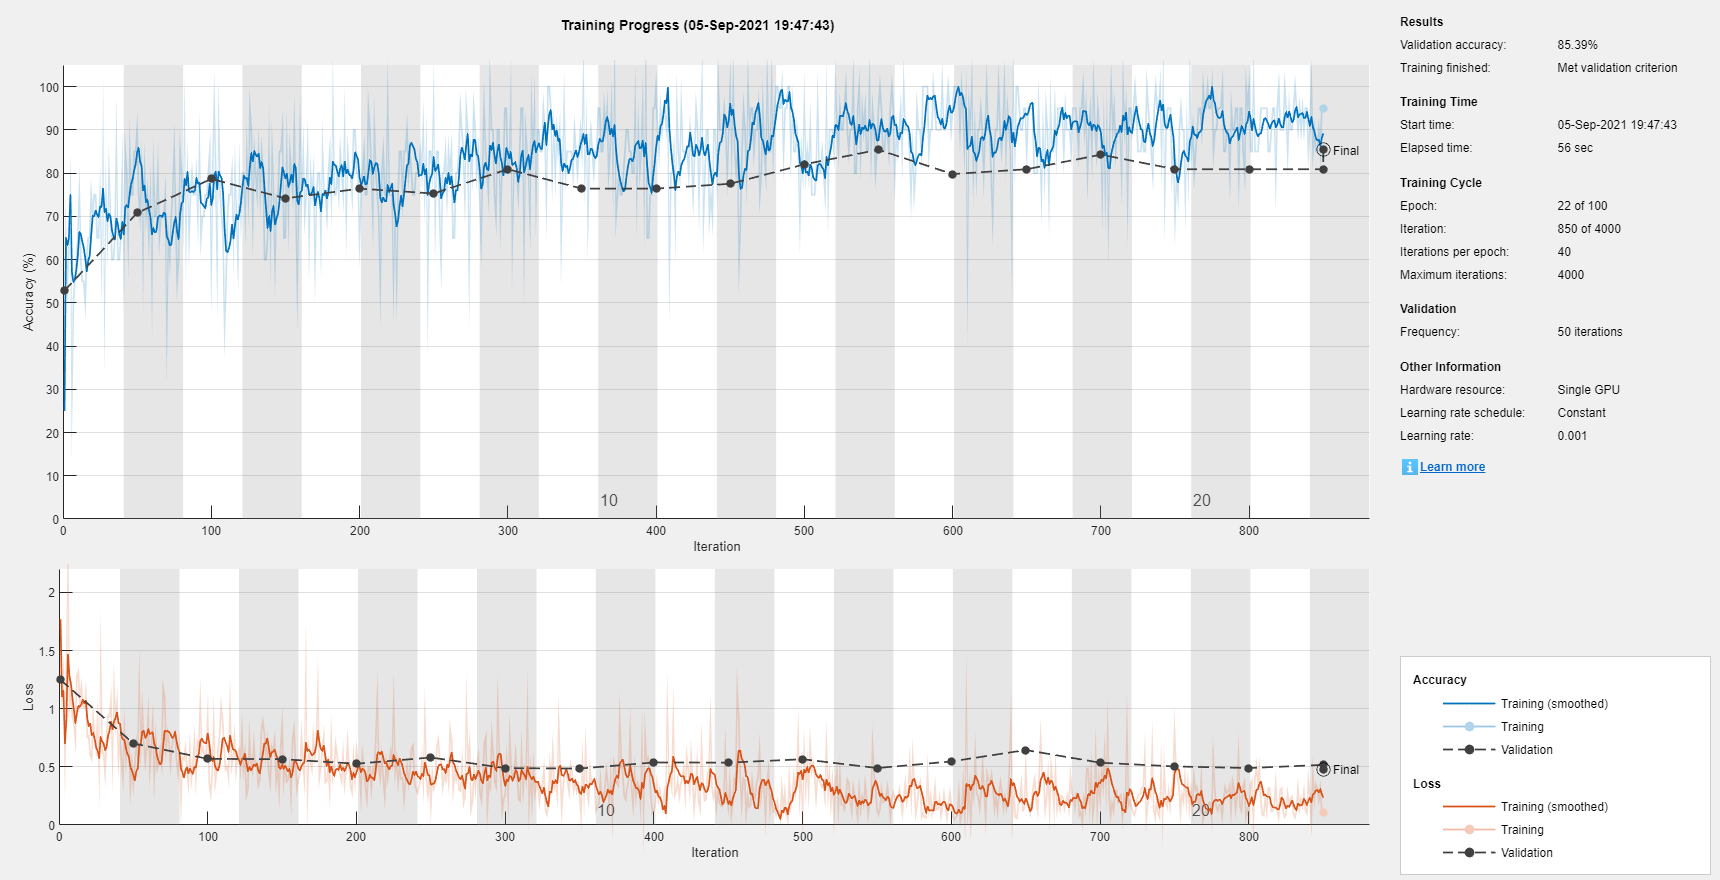

for a = 1:n_validationSet
    rng default
    [net{a},info{a}] = trainNetwork(xtrain{a},ytrain{a},layers,options{a});
    prediction{a} = classify(net{a},xval{a},'MiniBatchSize',parameters.minibatch);
    accuracy(a) = sum(prediction{a}==yval{a})/numel(yval{a});
end

crossval_accuracy = mean(accuracy)

crossval_accuracy = 0.8355

crossval_std = std(accuracy);

accuracy = round(accuracy*100,2);

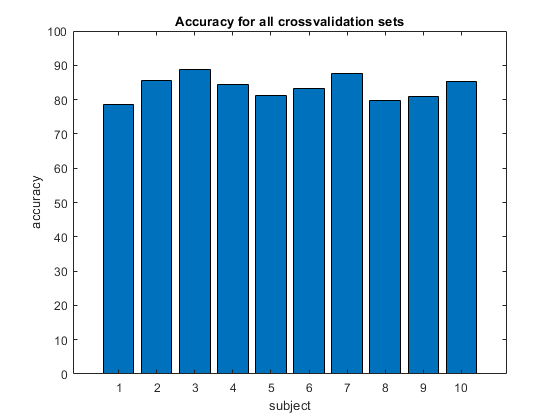

figure
bar(accuracy)
ylim([0 100])
title('Accuracy for all crossvalidation sets')
xlabel('subject')
ylabel('accuracy')


[val,ids] = max(accuracy)

val = 88.8900

ids = 3

best_network = net{ids};
session = 1:10;

results = table(session(:),accuracy(:),'VariableNames',{'cross-val session','Classification Accuracy'})

results = 10×2 table
    cross-val session    Classification Accuracy
    _________________    _______________________

            1                     78.65         
            2                     85.56         
            3                     88.89         
            4                     84.44         
            5                     81.11         
            6                     83.15         
            7                     87.64         
            8                     79.78         
            9                      80.9         
           10                     85.39         


mean_accuracy = round(mean(accuracy),2)

mean_accuracy = 83.5500

std_accuracy = std(accuracy);